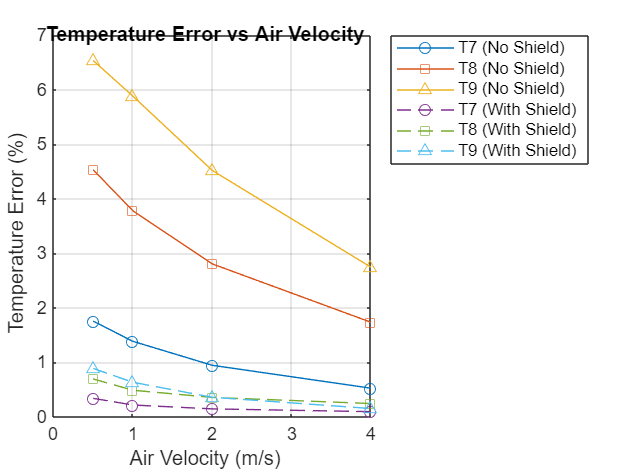

% % % disp(data ...
% % %     )
% % % 
% % % % Assuming your table is named "data"
% % % % Assign variables for clarity
% % T6_K = data.K;     % T6 in Kelvin
% % T7_K = data.K1;    % T7 in Kelvin
% % T8_K = data.K2;    % T8 in Kelvin
% % T9_K = data.K3;    % T9 in Kelvin
% % % 
% % % % Calculate the percentage error for each thermocouple
% % % error_T7 = 100 * (T7_K - T6_K) ./ T6_K;
% % % error_T8 = 100 * (T8_K - T6_K) ./ T6_K;
% % % error_T9 = 100 * (T9_K - T6_K) ./ T6_K;
% % % 
% % % 
% % % 
% % % value = data.K1(3);
% % % disp(value);
% % % disp(error_T7 ...
% % %     );
% % 
% T10_K = [403.15; 433.25; 473.45; 503.65];
% % 
% % T7_err = errorwithoutradiationshield.T_7Error(1:4);   % row 1 to 4 = U = 0
% T8_err = errorwithoutradiationshield.T_8Error(1:4);
% T9_err = errorwithoutradiationshield.T_9Error(1:4);
% T7_err = str2double(errorwithoutradiationshield.T_7Error(1:4));  % force numeric
% % 
% % 
% % disp(T10_K)
% % figure;
% % plot(T10_K, T7_err, '-o'); hold on;
% % plot(T10_K, T8_err, '-s');
% % plot(T10_K, T9_err, '-^');
% % hold off;
% % 
% % xlabel('Heated Wall Temperature T_{10} (K)');
% % ylabel('Temperature Error (%)');
% % title('Temperature Error vs. T_{10} Without Radiation Shield (Fan Off)');
% % legend('T7 Error', 'T8 Error', 'T9 Error', 'Location', 'northwest');
% % grid on;
% 
% T7_K = data.K1(1:4);  % replace 'data' with your actual table name
% T8_K = data.K2(1:4);
% T9_K = data.K3(1:4);
% 
% 
% deltaT_T7 = T10_K - T7_K;
% deltaT_T8 = T10_K - T8_K;
% deltaT_T9 = T10_K - T9_K;
% 
% 
% figure;
% plot(deltaT_T7, T7_err, '-o'); hold on;
% plot(deltaT_T8, T8_err, '-s');
% plot(deltaT_T9, T9_err, '-^');
% hold off;
% 
% xlabel('\DeltaT = T_{10} - T_{tc} (K)');
% ylabel('Temperature Error (%)');
% title('Error vs. ΔT (No Shield, Fan Off)');
% legend('T7', 'T8', 'T9', 'Location', 'northwest');
% grid on;


U = [0.5, 1, 2, 4];  % air velocities in m/s



T7_off = str2double(errorwithoutradiationshield.T_7Error(1:4));  % force numeric
T8_off = errorwithoutradiationshield.T_8Error(1:4);
T9_off = errorwithoutradiationshield.T_9Error(1:4);


T7_on = errorwithradiationshield.T_7Error(1:4);   % assuming rows 6 to 9 are U = 0.5 to 4, with shield
T8_on = errorwithradiationshield.T_8Error(1:4);
T9_on = errorwithradiationshield.T_9Error(1:4);



figure;

% No shield
plot(U, T7_off, '-o', 'DisplayName', 'T7 (No Shield)'); hold on;
plot(U, T8_off, '-s', 'DisplayName', 'T8 (No Shield)');
plot(U, T9_off, '-^', 'DisplayName', 'T9 (No Shield)');

% With shield
plot(U, T7_on, '--o', 'DisplayName', 'T7 (With Shield)');
plot(U, T8_on, '--s', 'DisplayName', 'T8 (With Shield)');
plot(U, T9_on, '--^', 'DisplayName', 'T9 (With Shield)');

xlabel('Air Velocity (m/s)');
ylabel('Temperature Error (%)');
title('Temperature Error vs Air Velocity');
legend('Location', 'northeastoutside');
grid on;


% 
% % Stefan-Boltzmann constant
% sigma = 5.67e-8;
% 
% % Air velocities (m/s)
% U = [0, 0.5, 1, 2, 4];
% 
% % Kelvin temps (4 rows each for U = 0.5 to 4)
% T6 = Withoutradiationshield.K(1:5);       % T_fluid
% T10 = Withoutradiationshield.K4(1:5);    % T_wall
% 
% % T7, T8, T9 thermocouple readings (no shield)
% T7 = Withoutradiationshield.K1(1:5);
% T8 = Withoutradiationshield.K2(1:5);
% T9 = Withoutradiationshield.K3(1:5);
% 
% % Emissivities
% eps_black = 1;    % T8 and T9
% eps_polished = 0.591;  % T7 
% 
% % Compute h for each
% h_T7 = eps_polished * sigma * (T10.^4 - T7.^4) ./ (T7 - T6);
% h_T8 = eps_black  * sigma * (T10.^4 - T8.^4) ./ (T8 - T6);
% h_T9 = eps_black  * sigma * (T10.^4 - T9.^4) ./ (T9 - T6);
% 
% % Plot
% figure;
% plot(U, h_T7, '-o', 'DisplayName', 'T7'); hold on;
% plot(U, h_T8, '-s', 'DisplayName', 'T8');
% plot(U, h_T9, '-^', 'DisplayName', 'T9');
% xlabel('Air Velocity (m/s)');
% ylabel('Convective Heat Transfer Coefficient, h (W/m^2·K)');
% title('h vs. Air Velocity (No Radiation Shield)');
% legend('Location', 'northwest');
% grid on;
% disp(T6);
% disp(T7);
% disp(h_T9);

